Initial parameters sizing: (ALL OF THESE HAVE TO BE DELEGATED, BUT ASSUMED FOR NOW)

The initial chosen airfoil (TOP SECRET DO NOT SHARE SG6043 [http://airfoiltools.com/airfoil/details?airfoil=sg6043-il](http://airfoiltools.com/airfoil/details?airfoil=sg6043-il)), with a Reynolds number of 50,000


clear; clc; clf; close all
R = 0.25; %Blade Radius (m)     INITIAL
R0 = 0.025; %Blade root (m)     Fixed
B = 3; %Blade number            INITIAL
AoA = deg2rad(8.75); %          INITIAL

Cl = @(aoa) 9.73 * (aoa - 0.0122);
Cl(AoA)

ans = 1.3672

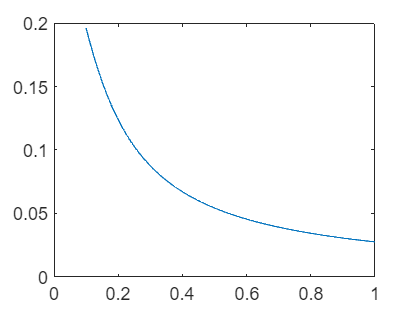

Cd = 0.038;

%Blade distribution             INITIAL
l = @(r) 7 * r / R;
phi = @(r) atan(2 / 3 ./ l(r));
chord = @(r) 8 / 3 * pi .* r .* sin(phi(r)).^2 ./ (B * 2 / 3 .* (1.3672 .* cos(phi(r)) + Cd .* sin(phi(r))));
plot((R0:0.001:R )/ R, chord(R0:0.001:R)./R)

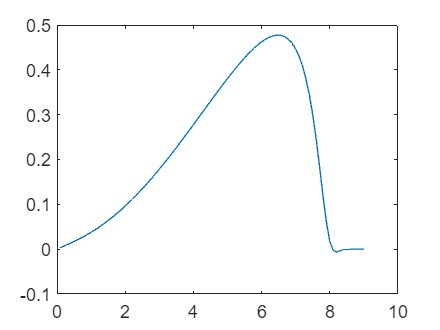

%Twist distribution             INITIAL
twist = @(r) atan(2 / 3 / (r / R)) - AoA;


N=100;
density = 1.225;
v_inf = 10;
I = 2*10^-4; % PER FIN
m = 0.03; % PER FIN

r_list = linspace(R0,R,N);
dr = r_list(2) - r_list(1);
dt = 0.001;
Cl = 1.45;
Cd = 0.038;

TSRList = 0:0.1:10;

PList = zeros(size(TSRList));
for TSR = TSRList
    Q = 0;
    for r = r_list
        a1 = 0;
        a2 = 0;
        v_a = v_inf * TSR / R;
        solidity = B / (2 * pi * r / R) * chord(r) / R;
        
        for i = 1:10
            W = sqrt(v_inf^2 * (1 - a1)^2 + r^2 * v_a^2 * (1 + a2)^2);
            sinphi = v_inf * (1 - a1) / W;
            cosphi = r * v_a * (1 + a2) / W;
            phi = asin(sinphi);
            aoa = phi - twist(r);
            
            Cx = Cl * cosphi + Cd * sinphi;
            Cy = Cl * sinphi - Cd * cosphi;
            
            eq1 = solidity * Cx / 4 / sinphi^2;
            eq2 = solidity * Cy / 4 / sinphi / cosphi;
        
            a1 = eq1 / (1 + eq1);
            a2 = eq2 / (1 + eq2);

            %a1 = 1 / (1 + 4 * sinphi^2 / solidity / Cl / cosphi);
            %a2 = 1 / (4 * cosphi / solidity / Cl - 1);
        end
        %Q = Q + (r/R)^2 * (8 * a2 * (1 - a1) * r / R - W / v_inf * B * chord(r) / R / pi * Cd * (1 + a2)) * dr/R;
        Q = Q + solidity * pi * density * v_inf^2 * (1 - a1)^2 / sinphi^2 * (Cl * sinphi - Cd * cosphi) * r^2 * dr;
    end
    %Q = Q / 2 * density * v_inf^2 * pi * R^3 * TSR;
    PList(TSRList==TSR) = Q * v_a / (1/2 * density * pi * R^2 * v_inf^3);
end
plot(TSRList, PList);

%plot(0:0.1:10, 4.*alist.*(1-alist).^2);

Functions